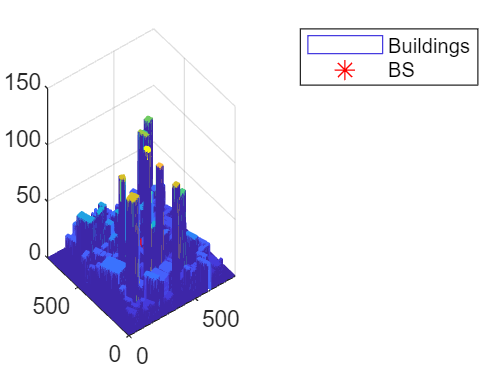

clc;
clear;
load('BldMap_trueHeight.mat');
%BS2Dloc=rand(1,2)*400+[200,200];%基站2D坐标在[200,600]x[200,600]
BS2Dloc=[400,400];
Bsloc_BldHeight=max([smallBldMap(ceil(BS2Dloc(1)),ceil(BS2Dloc(2))), 
                     smallBldMap(ceil(BS2Dloc(1)),floor(BS2Dloc(2))),
                     smallBldMap(floor(BS2Dloc(1)),ceil(BS2Dloc(2))), 
                     smallBldMap(floor(BS2Dloc(1)),floor(BS2Dloc(2)))]);

mesh(smallBldMap);
hold on;
%BSHeight=Bsloc_BldHeight+0.01;%基站高度取建筑物上的20m
BSHeight=Bsloc_BldHeight+0.01;
%BSHeight = 15;
BSloc=[BS2Dloc,BSHeight];
plot3(BSloc(1),BSloc(2),BSloc(3),'r*','markersize',10);
legend('Buildings','BS');
UAVheight=max(max(smallBldMap));%139m,Building最大高度129m
hold off;


%获取Building的3D坐标，每个（i，j）上的建筑物上的三维坐标，高度是建筑物最大高度
[NUM_X,NUM_Y]=size(smallBldMap);
Bld_grid_3Dloc=cell(NUM_X,NUM_Y);%NUM_X x NUM_Y x3 每个网格的3D位置
UAVgrid_Bs_dist=zeros(NUM_X,NUM_Y);
for i = 1:NUM_X
    for j = 1:NUM_Y
        temp = [i,j,smallBldMap(i,j)];
        Bld_grid_3Dloc{i,j} = temp;
        temp = [i,j,UAVheight];
        UAVgrid_Bs_dist(i,j) = norm(temp-BSloc);
    end
end

Map_grid = reshape(Bld_grid_3Dloc,[NUM_X*NUM_Y,1]);
Map_grid = cell2mat(Map_grid);
Map_grid(:,3) = UAVheight;

% 计算LSM (物理地图 2 LSM)
LSM = create_LSM(BSloc,smallBldMap,UAVheight);

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



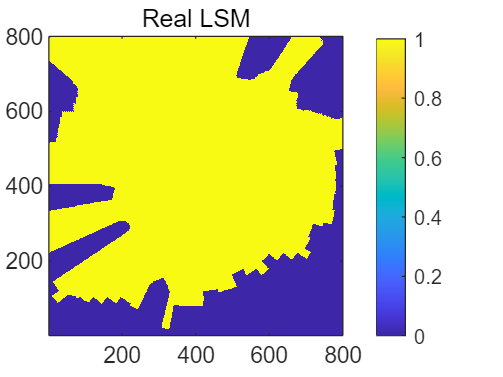

imagesc(LSM');
set(gca,'YDir','normal')
colorbar;
title('Real LSM')



fc = 28;%GHz


%beta1 = -18  - 20*log10(fc);
beta1 = -28  - 20*log10(fc);
altha1 = -2.2;
thegma1 = (4.64*exp(-0.0066*UAVheight))^2;
beta0 = 17.5 - 20*log10(40*pi*fc/3);
altha0 = -(46 - 7*log10(UAVheight))/10;
thegma0 = 6.25;
% thegma0 = 36;


Channel_LOS_Para = [beta1,altha1,thegma1];
Channel_NLOS_Para = [beta0,altha0,thegma0];
Channel_Para = [Channel_LOS_Para;Channel_NLOS_Para];
% 计算CGM每个位置上的信道参数。
CGM = create_CGM(LSM,UAVgrid_Bs_dist,Channel_Para);
CGM_mu = CGM(:,:,1);
CGM_var = CGM(:,:,2);


## Prior Map Calculation

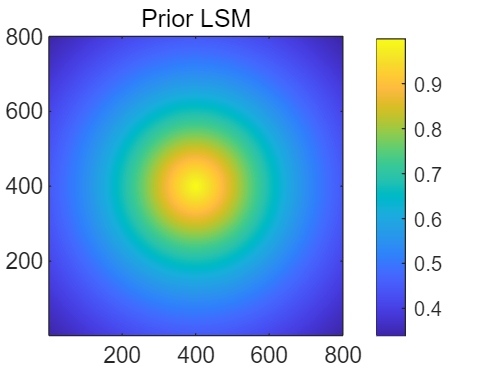

LSM_initial = LSMtheta_initial(UAVgrid_Bs_dist,UAVheight,BSHeight);
figure;
imagesc(LSM_initial);
set(gca,'YDir','normal')
colorbar;
title('Prior LSM')

## Initial Mutual Information Calculation

% 先验概率更新
LSM_prior = LSM_initial;

函数或变量 'LSM_initial' 无法识别。


H_L = Compute_PriorEntropy(LSM_prior); % 计算LSM地图先验熵
H_L_Mx = Compute_H_L_Mx(LSM_prior, x, Channel_Para); % 计算LSM在栅格x=(i,j)处测量获得的条件熵


I_L_M = H_L - H_L_M; % 计算LSM在位置x测量获得的互信息

% 寻找I_L_M中的最大值。
Index = max(I_L_M);


## Destination Calculation

% 
% 更新

